# 案例：牛顿型信赖域方法求解无约束问题

clear;clc;
x = OptTrustRegionNewton([0 0]', 1e-5, 1000)

x =     1.0000
    1.0000


f = fun(x)

f = 3.4655e-17

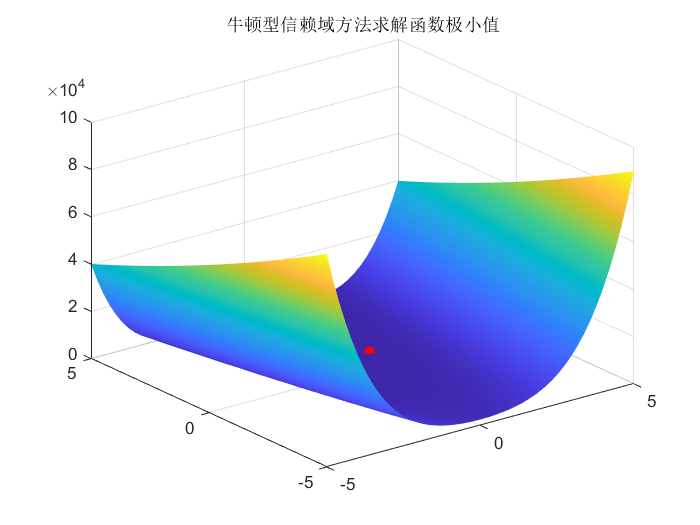

len = 50;
[xRange, yRange] = meshgrid(linspace(-5, 5, len), linspace(-5, 5, len));
z = nan(len, len);
for i = 1:len
    for j = 1:len   
        z(i, j) = fun([xRange(i, j), yRange(i, j)]);
    end
end
surf(xRange, yRange, z);
shading interp;
hold on
plot3(x(1), x(2), f, 'or', 'MarkerFaceColor', 'r');
hold off
title('牛顿型信赖域方法求解函数极小值');

function x = OptTrustRegionNewton(x0, err, MaxIter)
%{
函数功能：牛顿型信赖域方法求解无约束问题:  min f(x)；
输入：
  x0：初始点；
  err：梯度误差阈值；
  MaxIter：最大迭代次数；
输出：
  x：最小值点；
%}
if nargin < 3
   MaxIter = 10000;
end
if nargin < 2
   err = 1e-5;
end
if nargin < 1
   error('输入参数不足！');
end
eta1 = 0.1;  
eta2 = 0.75;
tau1 = 0.5;  
tau2 = 2.0;
delta = 1; 
dtabar = 2.0;
x = x0;
Bk = Hess(x);
k = 0;
while k < MaxIter 
    fk = fun(x);
    gk = gfun(x);
    if norm(gk) < err 
        break;
    end
    % 调用子程序 Trust_q
    [d, val] = Trust_q(fk, gk, Bk, delta);
    dq = fk - val;
    df = fun(x) - fun(x + d);
    rk = df/dq;
    if rk <= eta1 
        delta = tau1*delta;
    elseif rk >= eta2 && norm(d) == delta 
            delta = min(tau2*delta, dtabar);
    end
    if rk > eta1 
        x = x + d;
        Bk = Hess(x);
    end
    k = k+1;
end
end
function [d, val] = Trust_q(fk, gk, Bk, deltak)
%{
  函数功能: 求解信赖域子问题:
          min qk(d)=fk+gk'*d+0.5*d'*Bk*d, s.t.||d|| <= delta
输入: 
  fk：xk处的目标函数值；
  gk：xk处的梯度；
  Bk：近似 Hesse；
  delta：当前信赖域半径
输出: 
  d：最优值；
  val：最优值
%}
n = length(gk);
beta = 0.6;
sigma = 0.2;
mu0 = 0.05;
lam0 = 0.05;
gamma = 0.05;
d0 = ones(n, 1);
zbar = [mu0, zeros(1, n + 1)]';
i = 0;
mu = mu0;
lam = lam0;
d = d0;
while i <= 150
    H = dah(mu, lam, d, gk, Bk, deltak);
    if norm(H) <= 1e-8
        break;
    end
    J = JacobiH(mu, lam, d, Bk, deltak);
    b = psi(mu, lam, d, gk, Bk, deltak, gamma)*zbar - H;
    dz = J\b;
    dmu = dz(1); 
    dlam = dz(2); 
    dd = dz(3 : n + 2);
    m = 0; 
    mi = 0;
    while m < 20
        t1 = beta^m;
        Hnew = dah(mu + t1*dmu, lam + t1*dlam, d + t1*dd, gk, Bk, deltak);
        if norm(Hnew) <= (1 - sigma*(1 - gamma*mu0)*beta^m)*norm(H) 
            mi = m; 
            break;
        end
        m = m + 1;
    end
    alpha = beta^mi;
    mu = mu + alpha*dmu;
    lam = lam + alpha*dlam;
    d = d + alpha*dd;
    i = i + 1;
end
val = fk + gk'*d + 0.5*d'*Bk*d;
end


function p = phi(mu, a, b)
p = a + b - sqrt((a - b)^2 + 4*mu^2);
end


function H = dah(mu, lam, d, gk, Bk, deltak)
n = length(d);
H = zeros(n + 2, 1);
H(1) = mu;
H(2) = phi(mu, lam, deltak^2 - norm(d)^2);
H(3 : n + 2) = (Bk + lam*eye(n))*d + gk;
end


function J = JacobiH(mu, lam, d, Bk, deltak)
n = length(d);
t2 = sqrt((lam + norm(d)^2 - deltak^2)^2 + 4*mu^2);
pmu = -4*mu/t2;
thetak = (lam + norm(d)^2 - deltak^2)/t2;
J=[1,           0,          zeros(1, n);
   pmu,         1 - thetak, -2*(1 + thetak)*d';
   zeros(n, 1), d,          Bk + lam*eye(n)];
end


function si = psi(mu, lam, d, gk, Bk, deltak, gamma)
H = dah(mu, lam, d, gk, Bk, deltak);
si = gamma*norm(H)*min(1, norm(H));
end


function f = fun(x)
f = 100*(x(1)^2 - x(2))^2 + (x(1) - 1)^2;
end


function gf = gfun(x)
gf = [400*x(1)*(x(1)^2 - x(2)) + 2*(x(1) - 1);
      -200*(x(1)^2 - x(2))];
end


function He = Hess(x)
He = [400*(3*x(1)^2 - x(2)) + 2, -400*x(1);
      -400*x(1),                 200];
end